2.

x = [1 : 10];
t = [0.5 : 1 : 9.5];
y = sin(x);
yy = cos(x);

hold on;
fplot(@sin, [1, 10], 'r');

[a, b, c, d] = CubicSpline(x, y, 0, yy);
result = evaluate_spline(x, a, b, c, d, t);
fprintf("%f", result);

0.3193490.8572040.734543-0.063013-0.802820-0.804219-0.0672320.7353050.8478650.232932

plot(result, 'b');

3.

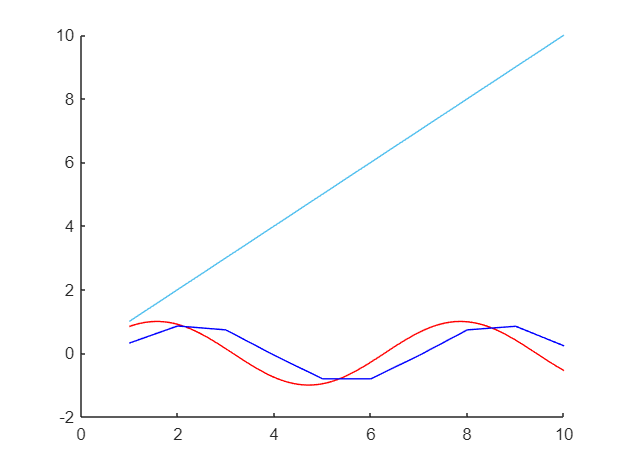

x = [1 : 10];
y = [1 : 10];

n = length(x);
tn = 0 : n - 1;
tg = linspace(0, n - 1, 1000);
xg = spline(tn, x, tg);
yg = spline(tn, y, tg);
plot(xg, yg);